ex 17.25 pag 405 dell hull

a)

S0= 0.95;
K=0.95;
Rusd=0.05;
Rcad=0.04;
sigma=0.08;
T=0.75;
[call,put]=blsprice(S0,K,Rusd,T,sigma,0.04)

call = 0.0290

put = 0.0221

oppure

F=S0*exp(0.01*0.75);
[call,put]=blkprice(F,K,0.05,T,sigma)

call = 0.0290

put = 0.0221

oppure

Sd=S0*exp(-0.04*0.75);
[call,put]=blsprice(Sd,K,0.05,0.75,sigma)

call = 0.0290

put = 0.0221

b) usare la put call parity per determinare il valore della put

Katt= K*exp(-0.05*0.75);
put=call+Katt-Sd

put = 0.0221

c)qual'è il valore di una call europea  con k=1 dollaro canadese scrtitta  con T=9mesi scritta su 0.95 dollari statunitensi

Kcad=1;
callcad=blsprice(1,Kcad,0.05,0.75,sigma,0.04)

callcad = 0.0305

callusd=callcad*0.95

callusd = 0.0290

simulazione montecarlo

ExpReturn = [Rusd-Rcad];
Sigmas = [sigma^2];
correlation=[sigma^2]

correlation = 0.0064

ExpCovariance = sigma^2

ExpCovariance = 0.0064

NumObs=189;
NumSim= 40000;
RetIntervals=1/252;
rng('default');  
RetExpected = portsim(ExpReturn, ExpCovariance, NumObs,RetIntervals, NumSim, 'Expected');
ExpSimulation=squeeze(RetExpected);

trovo i prezzi azionari

changerate= ret2tick(ExpSimulation,repmat(S0,1,NumSim))

changerate =     0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500    0.9500
    0.9562    0.9453    0.9474    0.9418    0.9494    0.9486    0.9499    0.9507    0.9501    0.9454    0.9481    0.9426    0.9442    0.9510    0.9486    0.9498    0.9481    0.9549    0.9482    0.9529    0.9485    0.9492    0.9482    0.9524    0.9456    0.9542    0.9616    0.9468    0.9454    0.9547    0.9447    0.9456    0.9547    0.9520    0.9432    0.9419    0.9443    0.9510    0.9492    0.9467    0.9578    0.9500    0.9564    0.9519    0.9531    0.9547    0.9563    0.9494    0.

istogramma

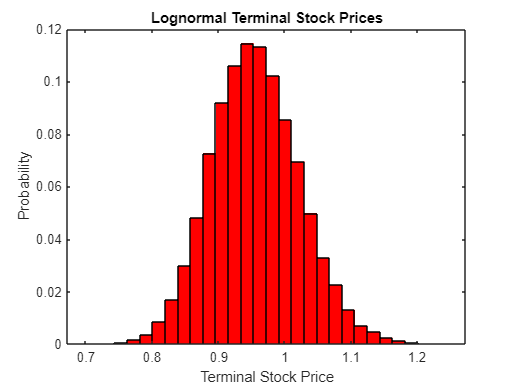

[count, BinCenter] = hist(changerate(end,:), 30);
figure(1)
bar(BinCenter, count/sum(count), 1, 'r')
xlabel('Terminal Stock Price')
ylabel('Probability')
title('Lognormal Terminal Stock Prices')

grafico

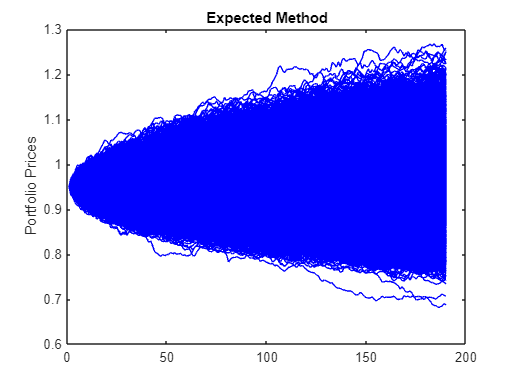

plot(changerate, '-b')
ylabel('Portfolio Prices')
title('Expected Method')

pricing call

term=changerate(189,:)';
payoff=(term-0.95);
payoff(payoff < 0) = 0;
callmontecarlo=mean(payoff)/exp(0.01*0.75)

callmontecarlo = 0.0293

pricing put

payoff1=(0.95-term);
payoff1(payoff1 < 0) = 0;
putmontecarlo=mean(payoff1)/exp(-0.01*0.75)

putmontecarlo = 0.0232